clear all
syms s Kc alpha beta phi
syms Kp Ki Kd

% Insertar planta:
% Ej. G_s = s/(s+1)
% G_s = 1/(10000*(s^2-1.772))
% G_s = 10/(s*(s+1))
G_s = 5/((s + 2)*(s + 1))

$$G\_s = \frac{5}{\left(s+1\right)\,\left(s+2\right)}$$


type = "PID";
Mpd =  0.10;
Tsd = 2;
Xid = -1;
Wnd = -1;



% Cero adicional para PID:
% extra_z_beta = NaN;
extra_z_beta = -1/2;

% ------------------------ Comienza código -------------------------------

Paso 1: Obtener Parámetros faltantes


% Cálculamos valores si hacen falta
[Wn, Xi, Mp, Ts] = completeVars(Wnd, Xid, Mpd, Tsd);

displayFormula("W_n = " + Wn)

$$W_{n}=3.3832$$

displayFormula("xi = " + Xi)

$$\xi =0.59116$$

Paso 2: Definir compensador

% Función comepnsador para cada caso
if type == 'PI'
    Gc_s = (Kc*(s + alpha))/s;
elseif type == 'PD'
    Gc_s = (Kc*(s + beta));
elseif type == 'PID'
    Gc_s = (Kc*(s + alpha)*(s + beta))/s;
end

disp(Gc_s)

$$\frac{\mathrm{Kc}\,\left(\alpha +s\right)\,\left(\beta +s\right)}{s}$$

Paso 3: Definir Ft de lazo abierto

% Planteamos FT de lazo abierto G_s*Gc_s
Gop_s = G_s*Gc_s;
disp(Gop_s)

$$\frac{5\,\mathrm{Kc}\,\left(\alpha +s\right)\,\left(\beta +s\right)}{s\,\left(s+1\right)\,\left(s+2\right)}$$

Paso 4: Encontrar polos

% Obtenemos numerador y denominador de la FT de lazo abierto
[num_Gop_s, den_Gop_s] = numden(Gop_s);
disp(den_Gop_s)

$$s\,\left(s+1\right)\,\left(s+2\right)$$

den_Gop_s = expand(den_Gop_s);
disp(den_Gop_s)

$$s^{3}+3\,s^{2}+2\,s$$

% Obtenemos polos y ceros del sistema igualando a cero
poles = solve(den_Gop_s == 0, s);
disp(den_Gop_s == 0)

$$s^{3}+3\,s^{2}+2\,s=0$$

**Polos del sistena**

poles = double(poles)

poles =     -2
    -1
     0


% Buscamos los ceros del sistema
zeros_sym = solve(num_Gop_s == 0, s);
is_numeric = arrayfun(@(z) isempty(symvar(z)), zeros_sym);
plant_zeros = double(zeros_sym(is_numeric));

Representamos el polinomio en si forma canónica y sustituimos


$$s^2 + 2\xi\omega_n s + \omega_n^2$$


% Buscamos polos dominantes con parámetros establecidos
Pd_s = s^2 + (2*Xi*Wn*s) + Wn^2;
disp(vpa(Pd_s))

$$s^{2}+4.0\,s+11.446091339691033539338604896329$$

**Polos deseados**


polesd = solve(Pd_s == 0, s);
polesd = double(polesd)

polesd =            -2 -     2.7288i
           -2 +     2.7288i


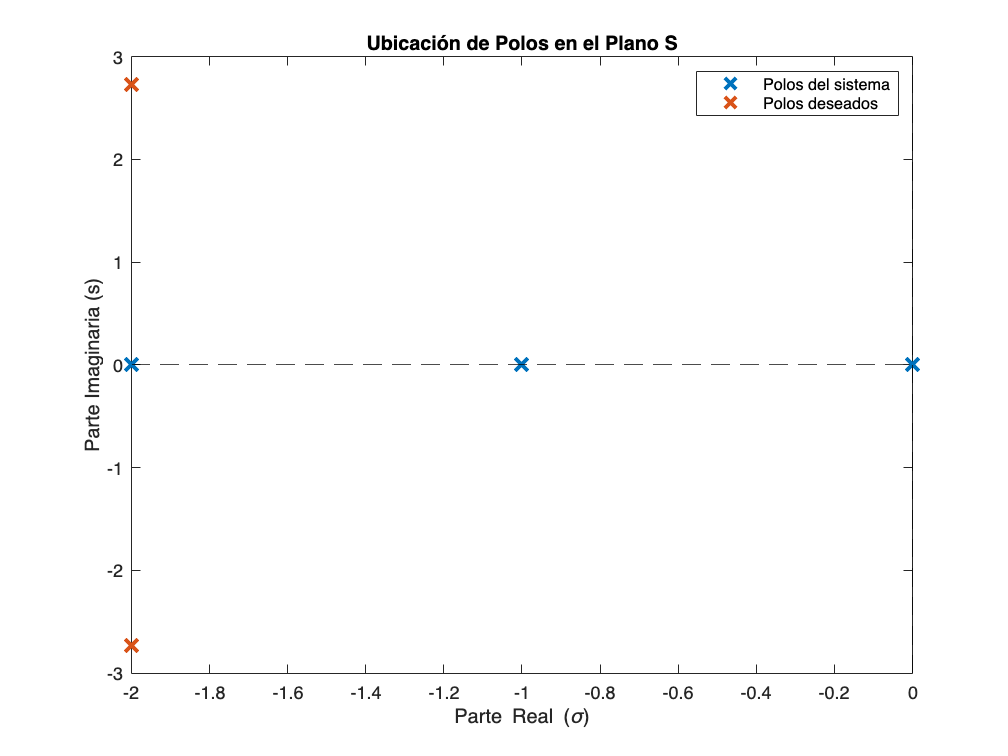


% Gráficamos los polos del sistema y los polos deseados

figure
plot(real(poles), imag(poles), 'x', ...
    'MarkerSize', 10, 'LineWidth', 2)

hold on

plot(real(polesd), imag(polesd), 'x', ...
    'MarkerSize', 10, 'LineWidth', 2)

xline(0, '--k') % Eje imaginario
yline(0, '--k') % Eje real
xlabel('Parte Real (\sigma)')
ylabel('Parte Imaginaria (s)')
title('Ubicación de Polos en el Plano S')
legend('Polos del sistema', 'Polos deseados')

hold off

Paso 5. Encontrar ángulos

% Encontrar ángulos de cada polo del sistema respecto a polo de interes
% Polo de interés:
sd = polesd(imag(polesd) > 0);
sd = sd(1);

% Cálculo de ángulos de polos
p_angles = arrayfun(@(p) rad2deg(abs(angle(sd-p))), poles);
disp(p_angles)

           90
       110.13
       126.24



z_angles = arrayfun(@(z) rad2deg(abs(angle(sd-z))), plant_zeros);
disp(z_angles)

Suma de angulos

% Suma de ángulos
angle_sum = sum(p_angles) - sum(z_angles);
fprintf('Sumatoria Ángulos = %f', angle_sum)

Sumatoria Ángulos = 326.365275

Verificamos si se necesitan angulos extra

% Verificamos si es necesario un cero extra y si se agrego
if type == "PID" && isnan(extra_z_beta)
        error("Se necesita un cero adicional para el controlador PID")
end

if type == "PID" && ~isnan(extra_z_beta)
    % Encontrar ángulo desde sd de phi2
    Z_beta_angle = rad2deg(abs(angle(sd-extra_z_beta)));
    angle_sum = angle_sum - Z_beta_angle;
end

Nueva suma de ángulos

fprintf('Sumatoria Ángulos = %f', angle_sum)

Sumatoria Ángulos = 207.567605


phi_angle = solve(angle_sum-phi == 180, phi);
phi_angle = double(phi_angle);
fprintf('phi = %f', phi_angle)

phi = 27.567605


% Cálculamos alfa ó beta
x = real(sd)-imag(sd)*(cosd(phi_angle)/sind(phi_angle));
fprintf('x = %f', x)

x = -7.226818


tolerance = 1e-8;
if abs(x) < tolerance
    x = 0;
end
x = round(x, 8); 

if type == "PI"
    alpha_val = -x;
    fprintf('alpha:');
    fprintf('%g\n', alpha_val);
elseif type == "PD"
    beta_val = -x;
    fprintf('beta:');
    fprintf('%g\n', beta_val);
elseif type == "PID"
    alpha_val = -x;
    beta_val = -extra_z_beta;
    fprintf('alpha:');
    fprintf('%g\n', alpha_val);
    fprintf('beta:');
    fprintf('%g\n', beta_val);
end

alpha:

7.22682


beta:

0.5


Paso 6. Usamos la condición de magnitud

% Usamos la condicón de magnitud para encontrar la ganancia
% Elimnar el Kc porque lo vamos a igualar
Gop_s_wKc = Gop_s/Kc;
disp(1/abs(Gop_s_wKc))

$$\frac{\left|s+1\right|\,\left|s+2\right|\,\left|s\right|}{5\,\left|\left(\alpha +s\right)\,\left(\beta +s\right)\right|}$$

Usamos alpha, beta y el punto deseado

disp(sd)

           -2 +     2.7288i



% Definimos valores de sustitución
if type == 'PI'
    old = [alpha, s];
    new = [alpha_val, sd];

elseif type == 'PD'
    old = [beta, s];
    new = [beta_val, sd];
    
elseif type == 'PID'
    old = [alpha, beta, s];
    new = [alpha_val, beta_val,  sd];
end

Kc_den = subs(Gop_s_wKc, old, new);
Kc_val = 1/abs(Kc_den);
Kc_val = double(Kc_val);
Kc_val = round(Kc_val, 8);

Valor de Kc

fprintf('Kc = %f', Kc_val)

Kc = 0.292265

Paso 7. Encontrar ganancias


if type == "PI"
    Kp_val = Kc_val;
    Ki_val = Kc_val*alpha_val;
    Kd_val = 0;
elseif type == "PD"
    Kp_val = Kc_val*beta_val;
    Ki_val = 0;
    Kd_val = Kc_val;
elseif type == "PID"
    Kp_val = Kc_val*(alpha_val + beta_val)
    Ki_val = Kc_val*alpha_val*beta_val;
    Kd_val = Kc_val;
end

Kp_val =        2.2583


fprintf('Kp: %f', Kp_val)

Kp: 2.258278

fprintf('Ki: %f', Ki_val)

Ki: 1.056073

fprintf('Kd: %f', Kd_val)

Kd: 0.292265



% simulink_PID_creator('TEST1', sym2tf(G_s), 1, Kp, Ki, Kd)